# Optimization design of rebar in a Two-Span concrete beam with surrogate-assistance

This figure below shows the rebar design prototype considered for optimization design (search space). A maximum of three different rebar diameter sizes can be placed both at top reinforcement and bottom reinforcement.

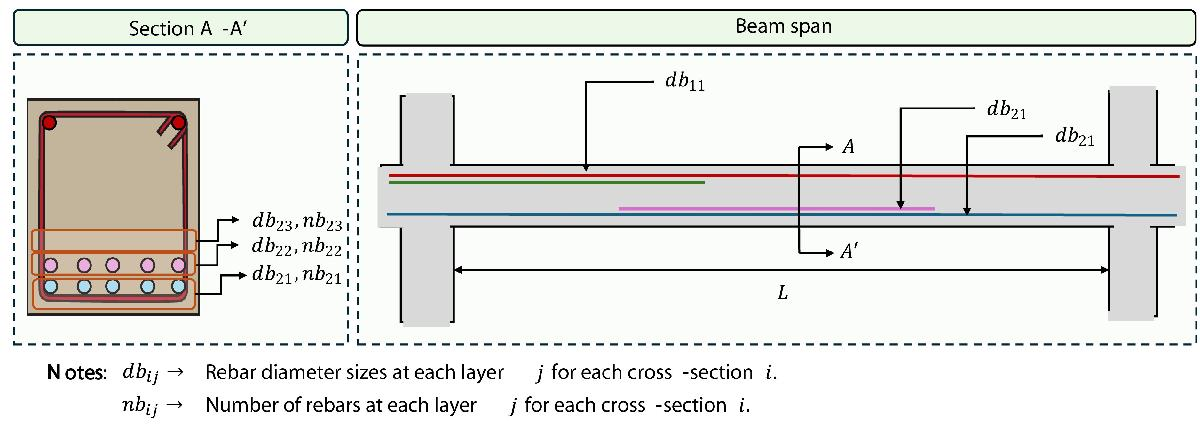

## Insert the folder path to store the rebar design results

Results will be stored as .csv files

directionData='C:\Users\luizv\OneDrive\CALDRECUST\Software\Package\Visual_CALDRECUST\Design_Data\RebarBeams\';

% If results are to be saved, input saveResults=true
saveResults=true

saveResults = logical
   1


Select the surrogate model for assistance during optimization "CPyRO" or "PlainGNN"

model2Use="CPyRO";

## Insert geometry of the beam element 

Lv=[4000;5000]; % mm
Totalspan = sum(Lv); % mm

bv=[300;300]; % mm
hv=[600;600]; % mm
        
hrec=50; % 
brec=50; % lateral concrete cover


## Insert material properties

### Concrete

fcuv=[35;35]; % MPa


### Steel reinforcement

fy=500; % Yield stress of steel reinforcement (N/mm2)
wac=7.85e-6; % unit volume weight of the reinforcing steel (Kg/mm3)

## Insert parameters for structural analysis with the FEM

### Create numerical model

% Discretization length
dL=100; % mm

% B.C.
supportsv=[0,4000,9000]; % mm


### Distributed loads 

Wv=[30,30;
    30,30]; % N/mm

Wrange=[0, 4000;
        4000, 9000]; % mm 
    
nspans=length(Wrange(:,1));


## **Analysis is executed**

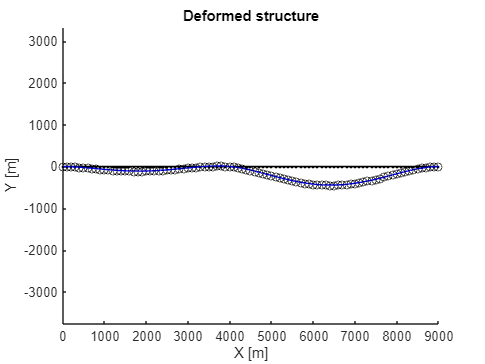

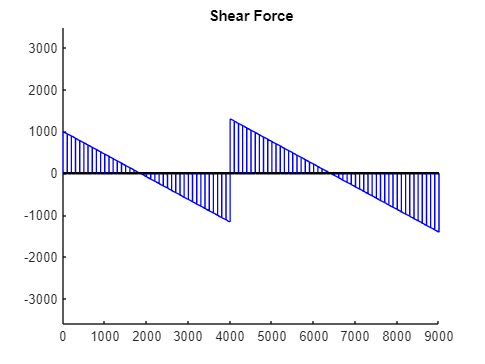

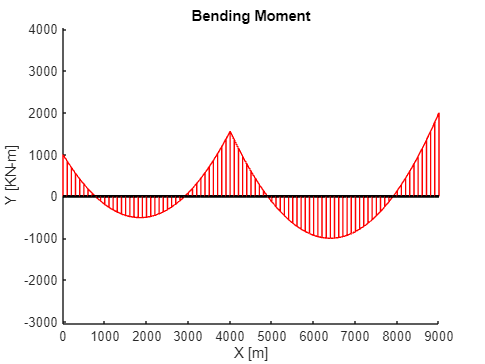

Ac = bv .* hv;
Ic = bv .* hv .^ 3 / 12;
Ec = (3.46 * sqrt(fcuv) + 3.21) .* 1e3;

[R,U,V,M]=MSFSFEMBeams(Totalspan,Ac,Ic,Ec,supportsv,Wv,dL,Wrange,1);

### Results from FEA are processed

The critical bending moments are extracted for the span (three main cross-sections left, mid and right). Based on the locations of these critical bending moments, the location of cuts is calcualted.

ne=zeros(1,nspans);
neSum=0;
load_conditions=[];
cutxLocMSBeams=[];
for i=1:nspans
    
    ne(i)=(supportsv(i+1)-supportsv(i))/dL;
    i1=neSum+1;
    Mleft(i,1)=M(1,i1);
    
    neSum=neSum+ne(i);
    Mright(i,1)=M(1,neSum);
    
    [Mmid(i,1),mp]=max(M(1,i1:neSum));
    load_conditions=[load_conditions;
                    i Mleft(i,1) Mmid(i,1) Mright(i,1)]; %Kg-cm (flexure)
    
    %% Cut location ( local coordinates)
    cutxLocBeam(i,:)=cutLocationSSRecBeam(M(:,i1:neSum),dL);
    cutxLocMSBeams=[cutxLocMSBeams,cutxLocBeam(i,:)];

    %% Location of design moments Mu - Data for PIGNN
    x0L(:,i)=[10,xMmid,Lv(i,1)-10]';
    
    %% Data for PIGNN or GNN
    DR(i,:)=[bv(i),hv(i),fcuv(i),Lv(i),Mleft(i),Mmid(i),Mright(i)];
end
nBeams=size(x0L,2);

## Rebar data

Aavialable commercial rebar diameters

% Format: [idx, diam (mm)]
rebarAvailable=[1 6;
                2 8;
                3 10;
                4 12;
                5 16;
                6 20;
                7 25;
                8 32;
                9 40
                10 50]; % mm^2

Additional design parameters 

dvs=10; % default diameter size for shear links

%% Maximum and minimum reinforcement percentage area
pmin=0.003;
pmax=0.025;

% Max aggregate size (mm)
hagg=20;

## Optmization design of longitudinal reinforcement

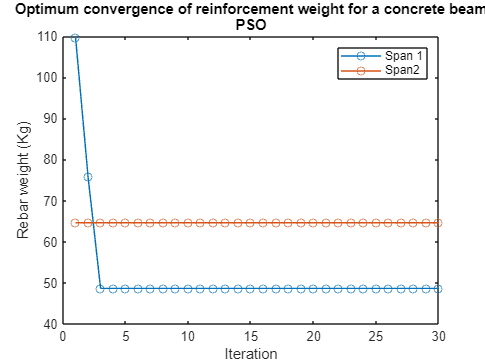

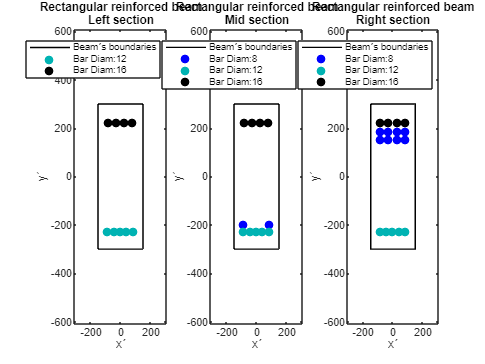

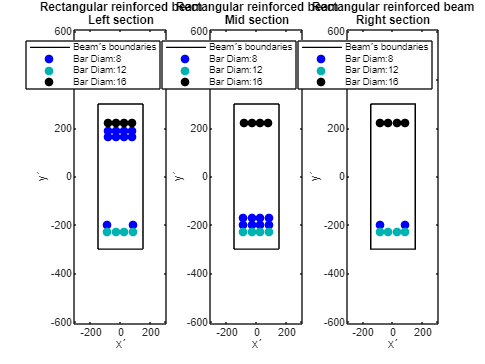

% Constructability weight factors (see documentation)
WUB=[0.6,0.7];
WND=[0.6];
WNB=[0.4];
WNC=[0.6,0.7];
Wcs1=2;
Wcs2=0.5;
WfaConstr=[WUB,WND,WNB,WNC,Wcs1,Wcs2];

%% Load surrogate models
% It is assumed that you have already added the path where the surrogate
% models are located
[Ao3]=NewPredBeams(DR,model2Use);

% Perform optimization design
[volRebarSpans,LenRebarL,LenRebarM,LenRebarR,sepRebarSpans,db9Spans,EffSpans,...
MrSpans,cSpans,ListRebarDiamLeft,ListRebarDiamMid,ListRebarDiamRight,...
DistrRebarLeft,DistrRebarMid,DistrRebarRight,tenbLMRspan,totnbSpan,...
CFAspans]=SASOOptimMSFSBeamsRebarSimple(bv,hv,Lv,brec,hrec,hagg,...
pmin,pmax,rebarAvailable([2:10]',:),fcuv,load_conditions,fy,wac,cutxLocBeam,...
Ao3,WfaConstr,1,1,[1,2],30,50);


if sum(db9Spans)==0
    return;
end

## **Process optimum design results for shear design**

dbLMRMSBeam=[];
ShearDesignMSBeam=[];
tenbLMRMSBeam=[];
totnbSpanMSBeams=[];
neSum=0;
for i = 1: nspans
    i1=neSum+1;
    
    neSum=neSum+ne(i);
    
    dbLMRMSBeam=[dbLMRMSBeam,db9Spans(i,:)];
    
    % Average percentage of cross-section reinforcement 
    rho=sum(tenbLMRspan(i,:).*(db9Spans(i,:).^2*pi/4))./(bv(i)*hv(i))/3;  
    
    % Execute shear design
    [s1(i,1),s2(i,1),s3(i,1),d1(i,1),d2(i,1)]=shearDesignBeams(Lv(i),bv(i),hv(i),...
                                            hrec,fcuv(i),fy,V(1,i1:neSum),dvs,rho);
    ShearDesignMSBeam=[ShearDesignMSBeam,...
                        s1(i,1),s2(i,1),s3(i,1),d1(i,1),d2(i,1),dvs];
    dvsBeams=dvs(1,1);
    
    % Decompose NbSpans matrix of size [ nspans x 9 ] into a vector of
    % size [ 1 x nspans * 9 ]       
    tenbLMRMSBeam=[tenbLMRMSBeam,tenbLMRspan(i,:)];
    totnbSpanMSBeams=[totnbSpanMSBeams,totnbSpan(i,:)];
end
ShearDesignMSBeams{1}=ShearDesignMSBeam;

nMSbeams=1;
beamNSb=zeros(nMSbeams,1);

## **Side rebars (if necessary)**

**In case the cross-section height of the beam is larger than 750 mm, then side rebars are provided to mitigate cracks**

if max(hv)>=750
    [dSb,nSb,sepSb,distrSideBars]=sideBarsRecBeams3SecSpan(max(bv),max(hv),fy,...
            brec,hrec,tenbLMRspan,db9Spans,dvs,hagg,rebarAvailable);
    
    beamNSb(1,1)=2*nSb;
    diamlistdSb=zeros(2*nSb,1)+dSb;
    
    plotBeamSideBar3sec(b,h,-DistrRebarLeft,ListRebarDiamLeft,...
            DistrRebarMid,ListRebarDiamMid,-DistrRebarRight,...
            ListRebarDiamRight,diamlistdSb,distrSideBars,nfig);
else
    distrSideBars=[];
    diamlistdSb=[];
end

diamlistdSbMSBeam{1}=diamlistdSb;
distrSbMSBeam{1}=distrSideBars;


## **Export results**

Input the desired file path to save the results to .csv files

if saveResults
    eleMSBeams{1}=[1,2];
    NbMSBeams{1}=tenbLMRMSBeam;
    DimMSBeams{1}=[bv',hv',Lv',brec,hrec];
    dbMSBeams{1}=dbLMRMSBeam;
    DecompCutxLocMSBeams{1}=cutxLocMSBeams;
    ListDiamLeftMSBeams{1}=ListRebarDiamLeft;
    ListDiamMidMSBeams{1}=ListRebarDiamMid;
    ListDiamRightMSBeams{1}=ListRebarDiamRight;
    LenRebarLeftMSBeams{1}=LenRebarL;
    LenRebarMidMSBeams{1}=LenRebarM;
    LenRebarRightMSBeams{1}=LenRebarR;
    DistrDiamLeftMSBeams{1}=DistrRebarLeft;
    DistrDiamMidMSBeams{1}=DistrRebarMid;
    DistrDiamRightMSBeams{1}=DistrRebarRight;
    NTotalMSBeams{1}=totnbSpanMSBeams;
    
    ExportDesignMSRecBeam(directionData,nMSbeams,eleMSBeams,DimMSBeams,...
        dbMSBeams,DecompCutxLocMSBeams,DistrDiamLeftMSBeams,DistrDiamMidMSBeams,...
        DistrDiamRightMSBeams,NTotalMSBeams,NbMSBeams,ListDiamLeftMSBeams,...
        ListDiamMidMSBeams,ListDiamRightMSBeams,LenRebarLeftMSBeams,...
        LenRebarMidMSBeams,LenRebarRightMSBeams,diamlistdSbMSBeam,distrSbMSBeam,...
        beamNSb,ShearDesignMSBeams)
end

## **Function appendix**


%% Function appendix
function [Ao3]=NewPredBeams(DR,model2Use)

% Data for GCNN
meanX=[349.605734767025	633.225806451613	37.4534050179212	4505.55555555556	-26339479.7363044];
sigsqX=[4949.66534345653	11216.8343161059	31.3195134954590	996295.300677007	2.10064997682719e+15];

[XTest,ATest]=predSurrogate(DR,meanX,sigsqX);

%% Load surrogate models
% Model for prediction of As per cross-section

if model2Use=="CPyRO"
    nheadsparamnGATPIGNN=load("nHeads_GAT_PIGNN_As_Section_4000.mat");
    paramPIGCNN=load("PIGCNN_As_Section_4000.mat");
    Ao3=PIGNNmodel1fc1GAT1Conv1fc(paramPIGCNN.pignn,XTest,ATest,nheadsparamnGATPIGNN.numHeads);

elseif model2Use=="PlainGNN"
    nheadsparamnGATGNN=load("nHeads_GAT_GCNN_As_Section_4000.mat");
    paramGCNN=load("GCNN_As_Section_4000.mat");
    Ao3=PlainGNNmodel1fc1GAT1Conv1fc(paramGCNN.parameters,XTest,ATest,nheadsparamnGATGNN.numHeads);

end
Ao3=extractdata(Ao3);

end

%% Function appendix

function [XTest,ATest]=predSurrogate(DR,meanX,sigsqX)

    sigsqX1=sigsqX(1);
    sigsqX2=sigsqX(2);
    sigsqX3=sigsqX(3);
    sigsqX4=sigsqX(4);
    sigsqX5=sigsqX(5);

    muX1=meanX(1);
    muX2=meanX(2);
    muX3=meanX(3);
    muX4=meanX(4);
    muX5=meanX(5);

    numObservations=length(DR(:,1));

    elements=[2 1 ;
              1 3];

    % Adjacency matrix
    numNodesGNN=3;
    % Adjancency matrix
    adjacency = zeros(numNodesGNN);
    for i = 1:size(elements,2)
        % The following logic specifies each node in an element is connected to
        % each other node in that element.
        nodesForElement = elements(:,i);
        for node = nodesForElement
            adjacency(nodesForElement,node) = 1;
        end
    end

    adjacency=repmat(adjacency,[1,1,numObservations]);

    X = [DR(:,1:7)];

    features1=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,5)];
    features2=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,6)];
    features3=[X(:,1),X(:,2),X(:,3),X(:,4),X(:,7)];

    XData1=zeros(numObservations,3,3);
    XData2=zeros(numObservations,3,3);
    XData3=zeros(numObservations,3,3);
    XData4=zeros(numObservations,3,3);
    XData5=zeros(numObservations,3,3);
    for i=1:numObservations
        features=[features1(i,:)',features2(i,:)',features3(i,:)'];

        for j=1:numNodesGNN
            XData1(i,j,j)=features(1,j);
            XData2(i,j,j)=features(2,j);
            XData3(i,j,j)=features(3,j);
            XData4(i,j,j)=features(4,j);
            XData5(i,j,j)=features(5,j);
        end
    end
    XData1 = double(permute(XData1, [2 3 1]));
    XData2 = double(permute(XData2, [2 3 1]));
    XData3 = double(permute(XData3, [2 3 1]));
    XData4 = double(permute(XData4, [2 3 1]));
    XData5 = double(permute(XData5, [2 3 1]));

    %% Partition of data
    % node adjacency data
    adjacencyDataTest = adjacency;

    % feature data
    coulombDataTest1 = XData1;
    coulombDataTest2 = XData2;
    coulombDataTest3 = XData3;
    coulombDataTest4 = XData4;
    coulombDataTest5 = XData5;

    %% Normalizing test data
    [ATest,XTest1] = preprocessData(adjacencyDataTest,coulombDataTest1);
    XTest1 = (XTest1 - muX1)./sqrt(sigsqX1);
    XTest1 = dlarray(XTest1);

    [~,XTest2] = preprocessData(adjacencyDataTest,coulombDataTest2);
    XTest2 = (XTest2 - muX2)./sqrt(sigsqX2);
    XTest2 = dlarray(XTest2);

    [~,XTest3] = preprocessData(adjacencyDataTest,coulombDataTest3);
    XTest3 = (XTest3 - muX3)./sqrt(sigsqX3);
    XTest3 = dlarray(XTest3);

    [~,XTest4] = preprocessData(adjacencyDataTest,coulombDataTest4);
    XTest4 = (XTest4 - muX4)./sqrt(sigsqX4);
    XTest4 = dlarray(XTest4);

    [~,XTest5] = preprocessData(adjacencyDataTest,coulombDataTest5);
    XTest5 = (XTest5 - muX5)./sqrt(sigsqX5);
    XTest5 = dlarray(XTest5);

    XTest=[XTest1,XTest2,XTest3,XTest4,XTest5];
end

function Y = PlainGNNmodel1fc1GAT1Conv1fc(parameters,X,A,numHeads)

    Z1 = X * parameters.Embedding.Weights + parameters.Embedding.b;

    weights1 = parameters.attn1.Weights;
    numHeadsAttention1 = numHeads.attn1;
    
    [Z2,~] = graphAttention(Z1,A,weights1,numHeadsAttention1,"cat");
    Z2  = relu(Z2);

    ANorm = normalizeAdjacency(A);
    Z3 = single(full(ANorm)) * Z2 * double(parameters.mult1.Weights);
    Z3  = relu(Z3) + Z2;

    Z4 = Z3 * parameters.Decoder.Weights + parameters.Decoder.b;
    
    Y = Z4;
end


function Y = PIGNNmodel1fc1GAT1Conv1fc(parameters,X,A,numHeads)

    Z1 = X * parameters.Embed.Weights + parameters.Embed.b;

    weights1 = parameters.attn1.Weights;
    numHeadsAttention1 = numHeads.attn1;
    
    [Z2,~] = graphAttention(Z1,A,weights1,numHeadsAttention1,"cat");
    Z2  = relu(Z2);

    ANorm = normalizeAdjacency(A);
    Z3 = single(full(ANorm)) * Z2 * double(parameters.mult1.Weights);
    Z3  = relu(Z3) + Z2;

    Z4 = Z3 * parameters.Decoder.Weights + parameters.Decoder.b;
    
    Y = Z4;
end

function [outputFeatures,normAttentionCoeff] = graphAttention(inputFeatures,...
    adjacency,weights,numHeads,aggregation)
    
    % Split weights with respect to the number of heads and reshape the matrix to a 3-D array
    szFeatureMaps = size(weights.linearWeights);
    numOutputFeatureMapsPerHead = szFeatureMaps(2)/numHeads;
    linearWeights = reshape(weights.linearWeights,[szFeatureMaps(1), numOutputFeatureMapsPerHead, numHeads]);
    attentionWeights = reshape(weights.attentionWeights,[numOutputFeatureMapsPerHead, 2, numHeads]);
    
    % Compute linear transformations of input features
    value = pagemtimes(inputFeatures,linearWeights);
    
    % Compute attention coefficients
    query = pagemtimes(value, attentionWeights(:, 1, :));
    key = pagemtimes(value, attentionWeights(:, 2, :));
    
    attentionCoefficients = query + permute(key,[2, 1, 3]);
    attentionCoefficients = leakyrelu(attentionCoefficients,0.2);
    
    % Compute masked attention coefficients
    mask = -10e9 * (1 - adjacency);
    attentionCoefficients = attentionCoefficients + mask;
    
    % Compute normalized masked attention coefficients
    normAttentionCoeff = softmax(attentionCoefficients,DataFormat = "BCU");
    
    % Normalize features using normalized masked attention coefficients
    headOutputFeatures = pagemtimes(normAttentionCoeff,value);
    
    % Aggregate features from multiple heads
    if strcmp(aggregation, "cat")
        outputFeatures = headOutputFeatures(:,:);
    else
        outputFeatures =  mean(headOutputFeatures,3);
    end

end


function varargout = trainingPartitions(numObservations,splits)
	%TRAININGPARTITONS Random indices for splitting training data
	%   [idx1,...,idxN] = trainingPartitions(numObservations,splits) returns
	%   random vectors of indices to help split a data set with the specified
	%   number of observations, where SPLITS is a vector of length N of
	%   partition sizes that sum to one.
	%
	%   % Example: Get indices for 50%-50% training-test split of 500
	%   % observations.
	%   [idxTrain,idxTest] = trainingPartitions(500,[0.5 0.5])
	%
	%   % Example: Get indices for 80%-10%-10% training, validation, test split
	%   % of 500 observations. 
	%   [idxTrain,idxValidation,idxTest] = trainingPartitions(500,[0.8 0.1 0.1])
	%{
	arguments
		numObservations (1,1) {mustBePositive}
		splits {mustBeVector,mustBeInRange(splits,0,1,"exclusive"),mustSumToOne}
	end
	%}
	numPartitions = numel(splits);
	varargout = cell(1,numPartitions);

	idx = randperm(numObservations);

	idxEnd = 0;

	for i = 1:numPartitions-1
		idxStart = idxEnd + 1;
		idxEnd = idxStart + floor(splits(i)*numObservations) - 1;

		varargout{i} = idx(idxStart:idxEnd);
	end

	% Last partition.
	varargout{end} = idx(idxEnd+1:end);

end

function ANorm = normalizeAdjacency(A)

	% Add self connections to adjacency matrix.
	A = A + speye(size(A));

	% Compute inverse square root of degree.
	degree = sum(A, 2);
	degreeInvSqrt = sparse(sqrt(1./degree));

	% Normalize adjacency matrix.
	ANorm = diag(degreeInvSqrt) * A * diag(degreeInvSqrt);

end

function [adjacency,features] = preprocessData(adjacencyData,coulombData)

    [adjacency, features] = preprocessPredictors(adjacencyData,coulombData);
    
end

function [adjacency,features] = preprocessPredictors(adjacencyData,coulombData)

    adjacency = sparse([]);
    features = [];
    
    for i = 1:size(adjacencyData, 3)
        % Extract unpadded data.
        numNodes = find(any(adjacencyData(:,:,i)),1,"last");
        
        A = adjacencyData(1:numNodes,1:numNodes,i);
        X = coulombData(1:numNodes,1:numNodes,i);
    
        % Extract feature vector from diagonal of Coulomb matrix.
        X = diag(X);
    
        % Append extracted data.
        adjacency = blkdiag(adjacency,A);
        features = [features; X];
    end

end

%------------------------------- end -----------------------------------